# TP SAE 22

BABINI Gabriel - 11b

## 3. Etude des bloc élémentaires

### Noise burst

Fe = 44100;         % Fréquence échantillonage (Hz)
F0 = 444;           % Fréquence de la note LA (Hz)
L = round(Fe/F0);   % Nbr d'échantillons (99)
d = 0.25            % Durée de la note 

d = 0.2500

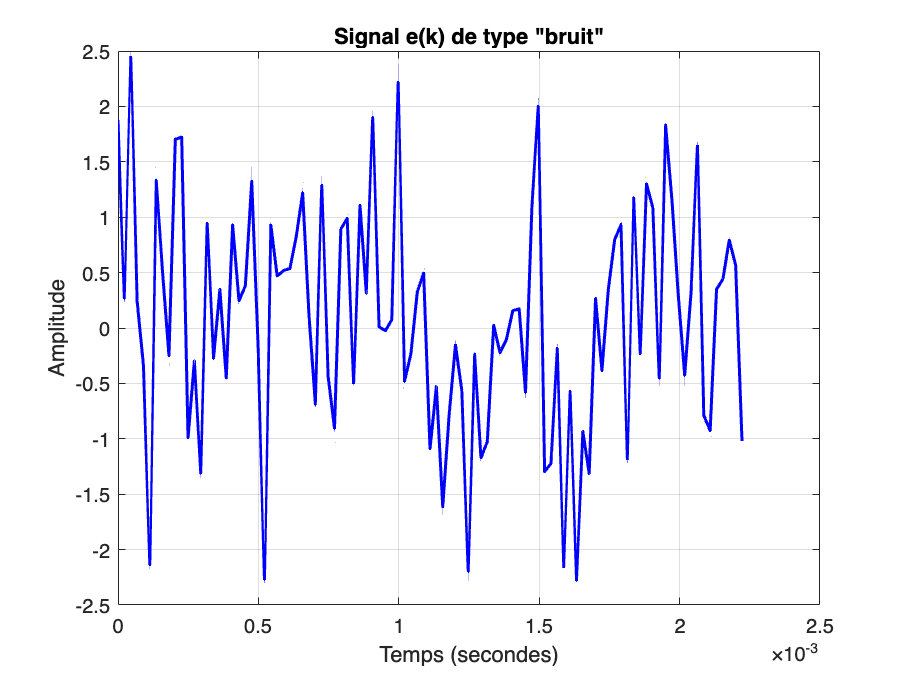

e = randn(1, L);    % Signal bruit
t = (0:L-1) / Fe;   % Période

figure;             % Figure de e(k)
plot(t, e, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Temps (secondes)');
ylabel('Amplitude');
title('Signal e(k) de type "bruit"');

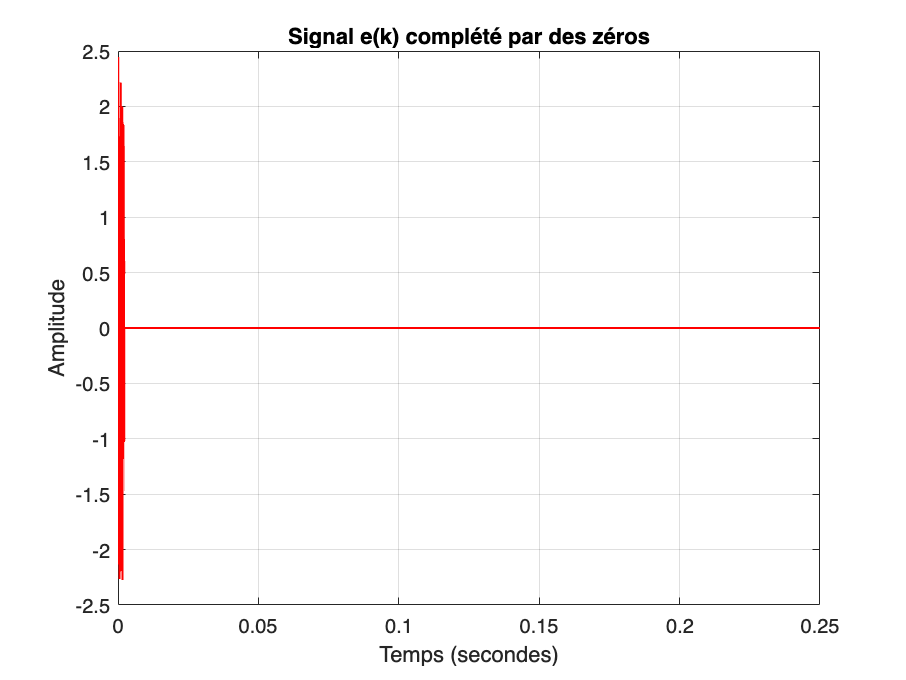


N   = round(d * Fe);
e_N = [e, zeros(1, N - L)];
t_N = (0:N-1) / Fe;

figure;               % Figure de e(k) complété
plot(t_N, e_N, 'r-', 'LineWidth', 1);
grid on;
xlabel('Temps (secondes)');
ylabel('Amplitude');
title('Signal e(k) complété par des zéros');

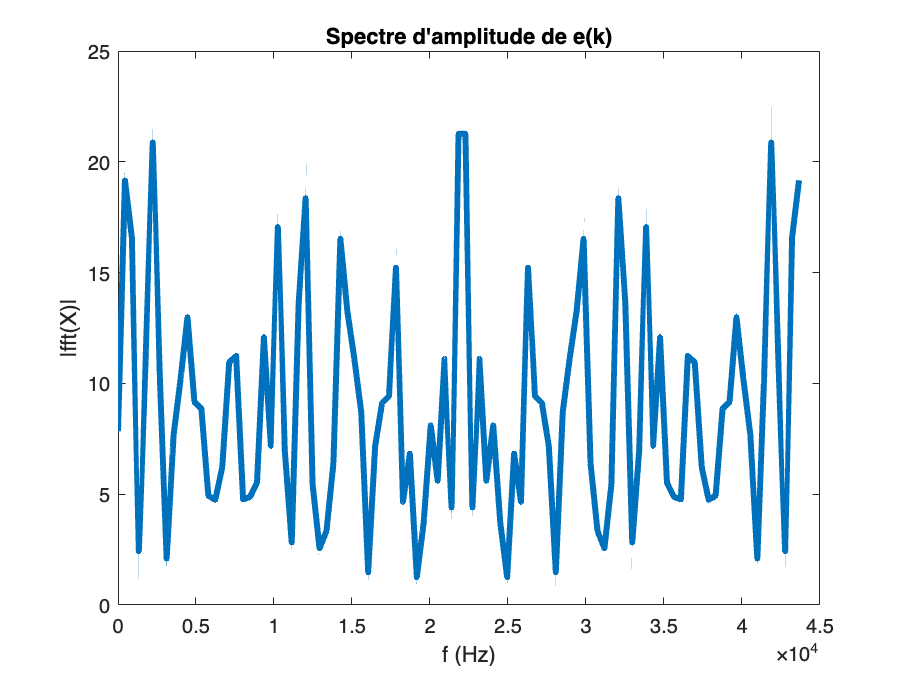


Y = fft(e);           % Spectre d'amplitudes de e(k)
plot(Fe/L*(0:L-1),abs(Y),"LineWidth",3)
title("Spectre d'amplitude de e(k)")
xlabel("f (Hz)")
ylabel("|fft(X)|")

### Filtrage passe-bas

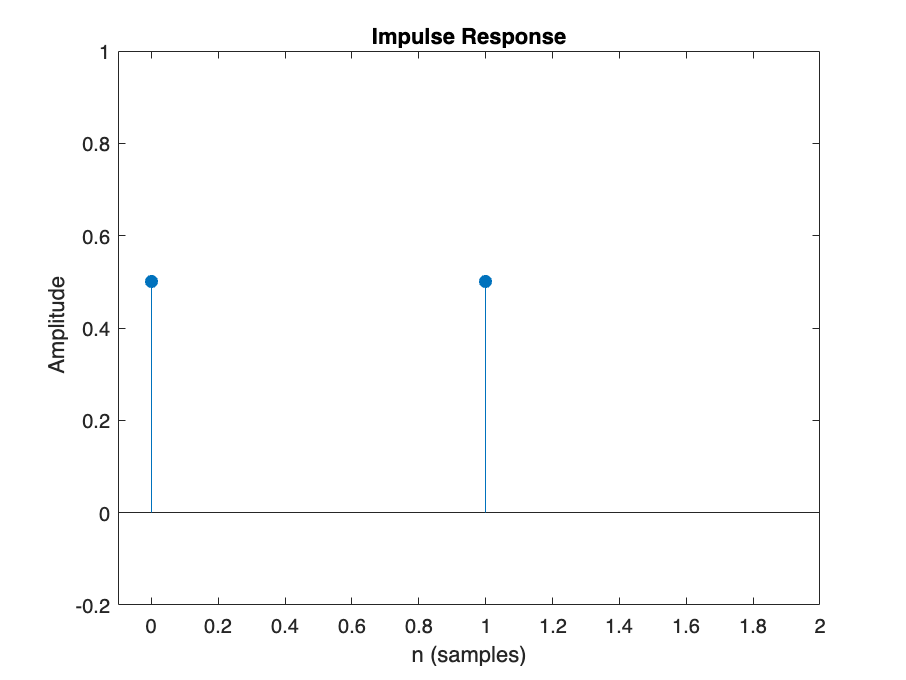

h=[1/2 1/2];
figure,
impz(h); axis ([-0.1 2 -0.2 1]);

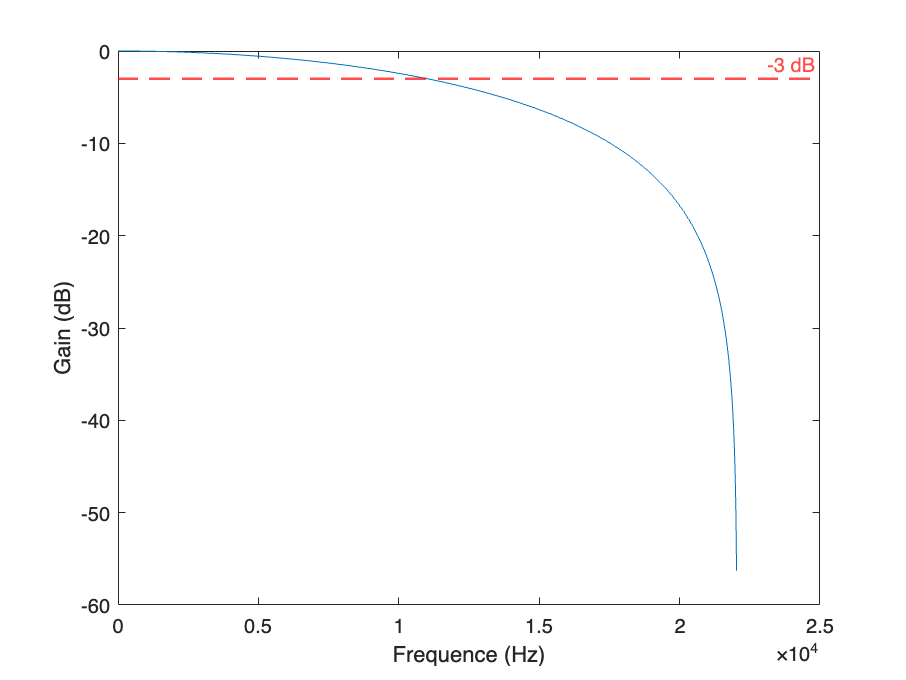

Nf=1024;
[H,freq] = freqz(h,1,Nf,Fe);
plot(freq,20*log10(abs(H)));
yline(-3, 'r--', '-3 dB', 'LineWidth', 1.2);
xlabel('Frequence (Hz)'); ylabel('Gain (dB)');

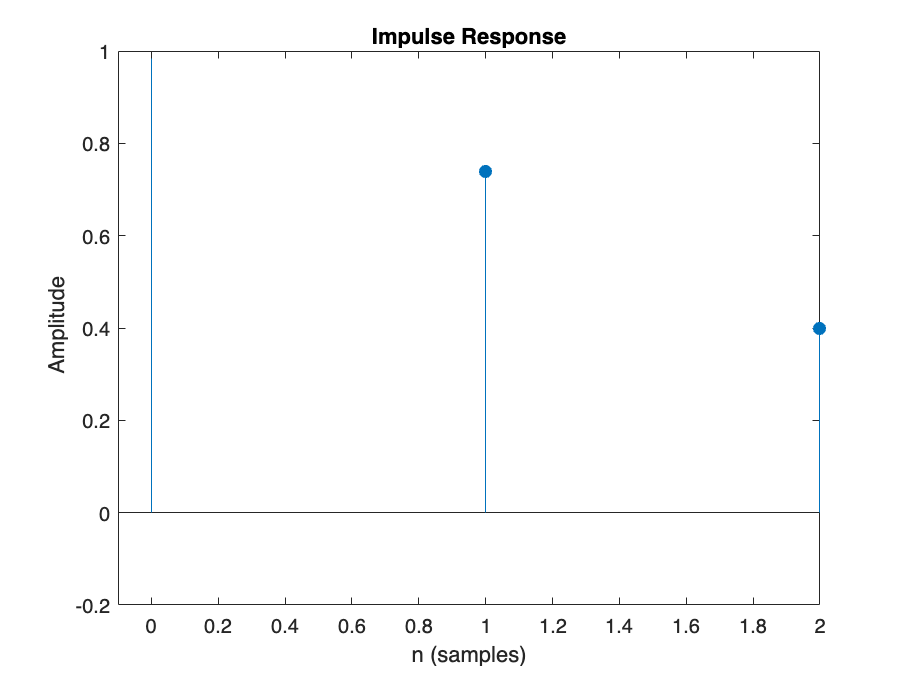


N = 100;
bk = randn(1, N);
figure,
impz(bk); axis([-0.1 2 -0.2 1]);

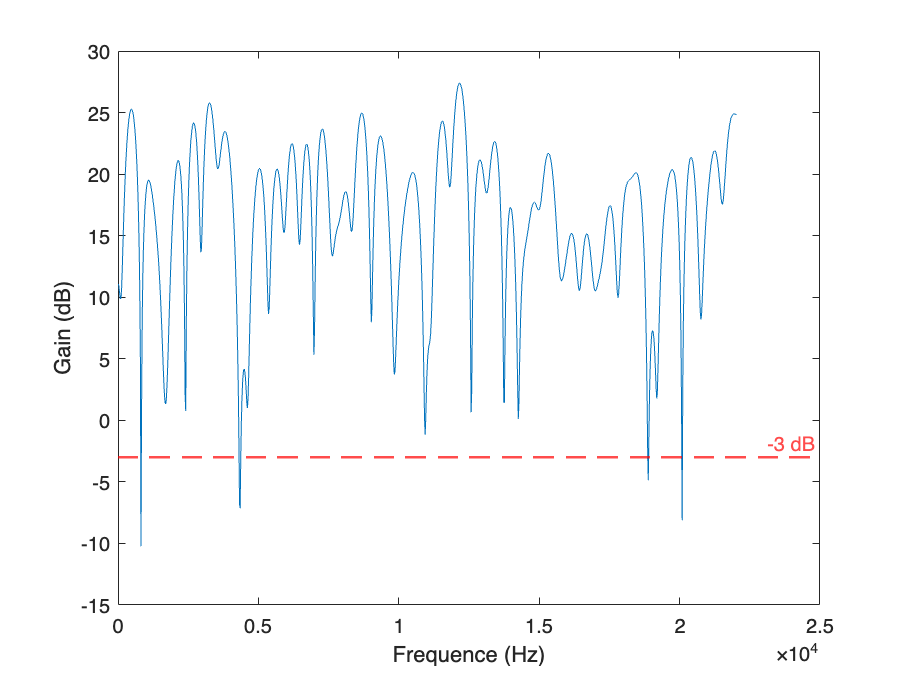

[H, freq] = freqz(bk, 1, Nf, Fe);
plot(freq, 20*log10(abs(H)));
yline(-3, 'r--', '-3 dB', 'LineWidth', 1.2);
xlabel('Frequence (Hz)'); ylabel('Gain (dB)');

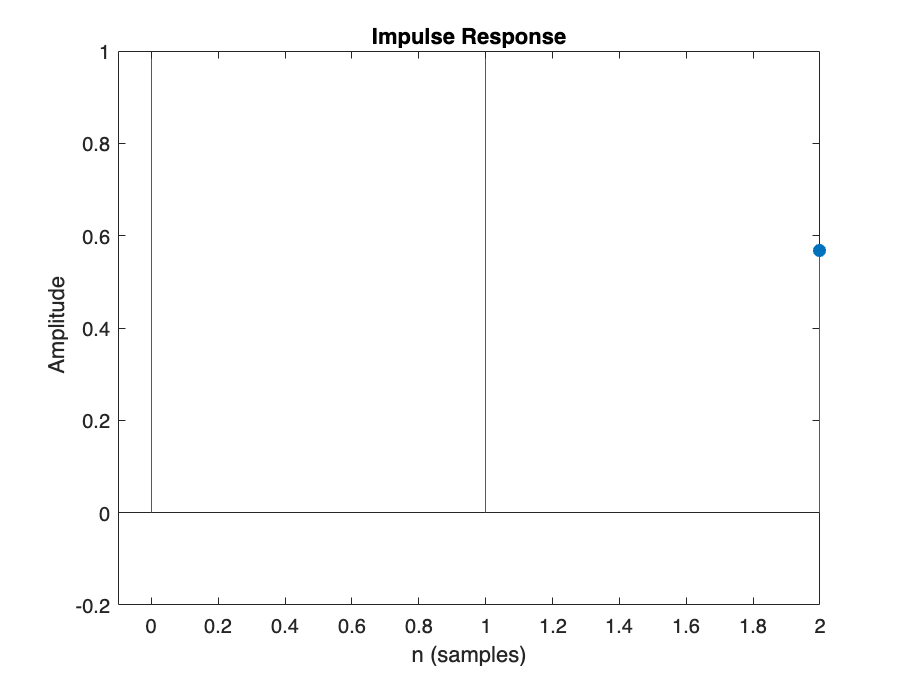


yk(1) = bk(1);
for k = 2:length(bk)
    yk(k) = (1/2)*bk(k) + (1/2)*bk(k-1);
end

figure,
impz(yk); axis([-0.1 2 -0.2 1]);

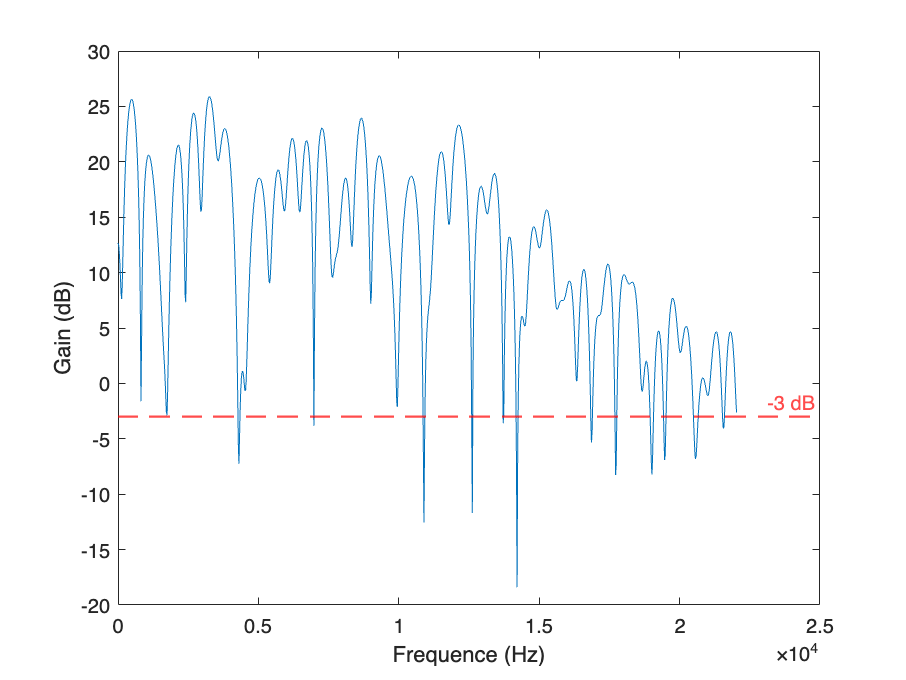

[H, freq] = freqz(yk, 1, Nf, Fe);
plot(freq, 20*log10(abs(H)));
yline(-3, 'r--', '-3 dB', 'LineWidth', 1.2);
xlabel('Frequence (Hz)'); ylabel('Gain (dB)');

## 4. Algorithme de Karplus-Strong

clear; close all;
Fe = 44100;                     % frequence d echantillonnage en Hz
F0 = 440;                       % frequence de la note en Hz: ex. DO=262, LA=440
a = 1;                          % relaxation de la note (entre 0 et 1, 1=relax min)
d = .25;                        % duree de la note en secondes (250 ms)
L = round(Fe/F0);               % calcul de L
N = round(d*Fe);                % nombre d echantillons du signal
e = [randn(1,L), zeros(1,N-L)]; % signal d entree
s = zeros(1,N);                 % signal de sortie (note)
x = zeros(1,N);                 % entree du filtre
y = zeros(1,N);                 % sortie du filtre
DL = zeros(1,L);                % ligne a retard de longueur L

for k=2:N
    x(k) = DL(L);                        % sortie de DL
    y(k) = (a/2) * (x(k) + x(k-1));      % filtrage passe-bas
    s(k) = e(k) + y(k);                  % calcul de la sortie
    DL(2:L) = DL(1:L-1);                 % decalage vers la gauche
    DL(1) = s(k);                        % entree du nouvel élément
end
soundsc(s,Fe);

son = Karplus(600,1,1)      % Pour produire une note 

son =          0    0.8966   -0.8230    1.5353    1.8025   -0.4918   -0.7772   -2.5273   -0.2977   -0.5764    1.6771   -0.8127    0.9188   -1.7009   -0.4611   -0.4419    0.2388   -0.0796   -1.8116   -0.4488    0.1530   -1.5145   -1.0772    1.0484    0.5163    1.0830   -0.6705   -2.0540   -0.2549   -0.3394    0.3317    1.0307    0.7246    1.2312    0.1134    0.0316    0.5844    0.9148   -0.2955    0.8417   -0.7184   -0.3510    0.3258    0.0874   -2.4528    1.4987    0.8548    0.7226   -0.0206    0.0989


soundsc(son, Fe);        
% D'avantage a est faible, d'avantage le son est aigu

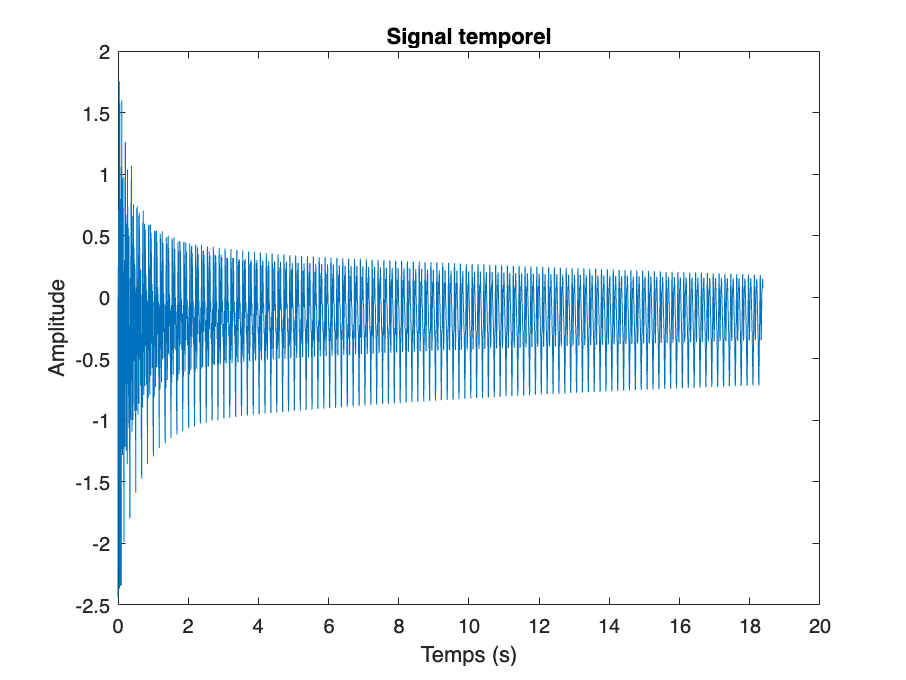

Fe = 600;

% Signal temporel
figure,
t = (0:N-1)/Fe;
plot(t, s);
xlabel('Temps (s)'); ylabel('Amplitude');
title(['Signal temporel']);

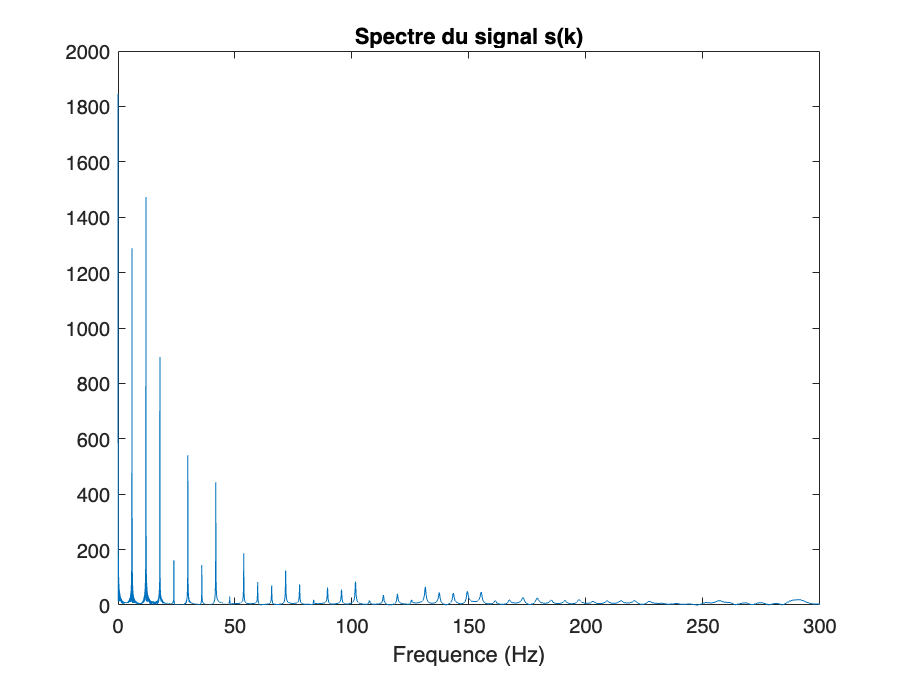


% Spectre
figure,
S = abs(fft(s, 2^nextpow2(length(s))));
S = S(1:end/2);
f = [0:length(S)-1]/length(S)*Fe/2;
plot(f, S);
xlabel('Frequence (Hz)');
title('Spectre du signal s(k)');

Fe = 44100; 
son = Karplus(277, 1, 2);
soundsc(son, Fe);

% Deux notes différentes à la suite 
KarplusSuite(277,294)

% Deux notes cummulés
KarplusCombine(277,294)

#### Notes de musiques (en Hz)

### Pédale d'effet pour guitare 

https://fr.mathworks.com/matlabcentral/fileexchange/11582-guitar-effects-pedal-pedale-d-effet-pour-guitare

Fe = 44100;
s_total = Karplus(440, 1, 1);
s_col   = s_total(:);           

% Distorsion
s_dist = effet_distortion(s_col, Fe, 10);
soundsc(s_dist, Fe);

% Delay
s_delay = effet_delay(s_col, Fe, 0.5, 150);
soundsc(s_delay, Fe);

% Reverb
s_reverb = effet_reverb(s_col, Fe, 80, 0.4);
soundsc(s_reverb, Fe);

% Flanger
s_flange = effet_flange(s_col, Fe, 2);
soundsc(s_flange, Fe);

% Chorus
s_chorus = effet_chorus(s_col, Fe, 0.7);
soundsc(s_chorus, Fe);

% Multiple echoes
s_echoes = effet_multiplechoes(s_col, Fe, 0.6, 100);
soundsc(s_echoes, Fe);

% Chaîner deux effets
s_chain = effet_distortion(s_col, Fe, 0.8);
s_chain = effet_reverb(s_chain, Fe, 80, 0.4);
soundsc(s_chain, Fe);

% Effet réduction bits (effet rajouté)
guitare_claire = Karplus(F0, a, 1);
guitare_retro = effet_bitcrusher(guitare_claire, 2);
soundsc(guitare_retro, Fe);

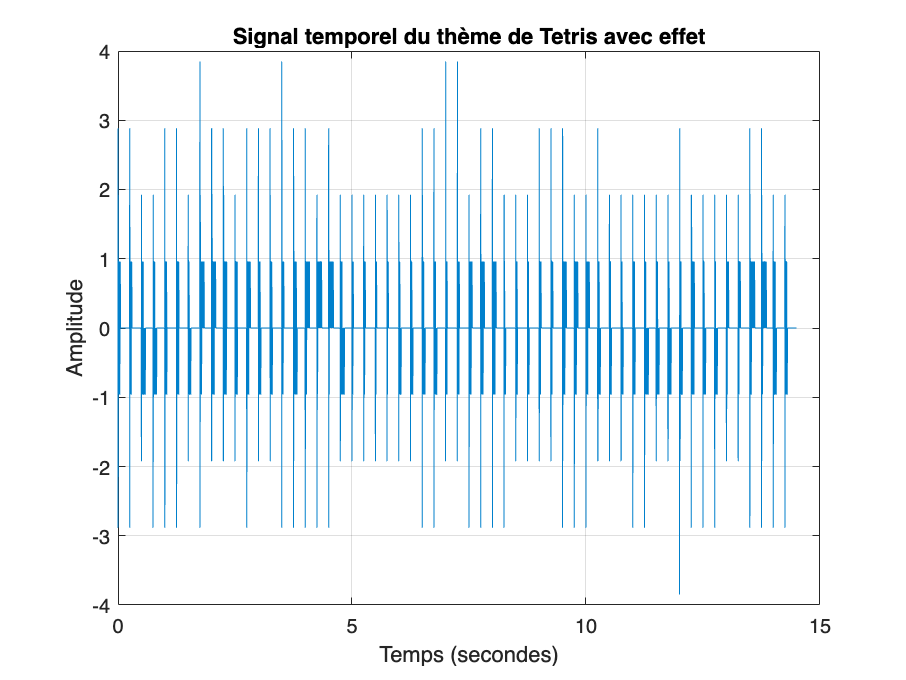

% Nettoyage de l'espace de travail et fermeture des figures ouvertes
clear; close all;

% --- Paramètres généraux du signal ---
Fe = 44100; % Fréquence d'échantillonnage en Hz
a = 0.99;   % Coefficient d'atténuation pour l'algorithme de Karplus-Strong (définit le temps de résonance)

% --- Définition des fréquences des notes (en Hz) ---
Mi4 = 659;  Si3 = 494;  Do4 = 523;  Re4 = 587;  
La3 = 440;  Fa4 = 698;  La4 = 880;  Sol4 = 784;

% --- Partition du thème de Tetris (Korobeiniki) ---
% Vecteur contenant la séquence mélodique (les hauteurs)
notes_freq = [ ...
    Mi4, Si3, Do4, Re4, Do4, Si3, La3, La3, Do4, Mi4, Re4, Do4, Si3, Do4, Re4, Mi4, Do4, La3, La3, ... 
    Re4, Fa4, La4, Sol4, Fa4, Mi4, Do4, Mi4, Re4, Do4, Si3, Do4, Re4, Mi4, Do4, La3, La3 ...         
];

% Vecteur contenant la durée relative de chaque note correspondante (le rythme)
notes_durees = [ ...
    2, 1, 1, 2, 1, 1, 2, 1, 1, 2, 1, 1, 3, 1, 2, 2, 2, 2, 2, ... 
    3, 1, 2, 1, 1, 3, 1, 2, 1, 1, 2, 1, 1, 2, 2, 2, 2 ...         
];

% Initialisation du vecteur vide qui contiendra le signal audio final
tetris_brut = [];

% --- Synthèse sonore ---
% Boucle pour générer et assembler chaque note une par une
for i = 1:length(notes_freq)
    % Génération du signal de la note actuelle via ton implémentation de Karplus-Strong
    note_actuelle = Karplus(notes_freq(i), a, notes_durees(i));
    
    % Concaténation de la nouvelle note à la suite du signal global
    tetris_brut = [tetris_brut, note_actuelle];
end

% --- Traitement du signal (Effet Audio) ---
% Application d'un effet de type "bitcrusher"
tetris_personnalise = effet_bitcrusher(tetris_brut, 2);

% --- Lecture de l'audio ---
soundsc(tetris_brut, Fe);           % Lecture de la mélodie sans effets (soundsc normalise l'amplitude)

% Pause calculée sur la durée totale du morceau (+ 1 seconde de marge) 
% pour éviter que les deux pistes audio ne se superposent lors de l'exécution
pause(length(tetris_brut)/Fe + 1);

soundsc(tetris_personnalise, Fe);   % Lecture de la version avec l'effet bitcrusher appliqué

% --- Affichage graphique ---
figure;
% Création du vecteur temps en secondes en divisant le nombre d'échantillons par Fe
t = (0:length(tetris_personnalise)-1) / Fe;

% Tracé du signal temporel de la version modifiée
plot(t, tetris_personnalise, 'Color', [0 0.5 0.8]);
title('Signal temporel du thème de Tetris avec effet');
xlabel('Temps (secondes)');
ylabel('Amplitude');
grid on; % Ajout d'une grille pour faciliter la lecture du graphique